# Unit 4.3: Fourier Transforms for Circuit and LTI Analysis

Prepared for EG-247 Digital Signal Processing by Dr C.P. Jobling

## Example 3

Karris example 8.10: for the linear network shown below, the input-output relationship is:


$$$$\frac{d}{dt}v_{\mathrm{out}}+4v_{\mathrm{out}}=10v_{\mathrm{in}}$$$$


where $v_{\mathrm{in}}=3e^{-2t}$. Use the Fourier transform method, and the system function $H(\omega)$ to compute the output $v_{\mathrm{out}}$ Verify the result with MATLAB.

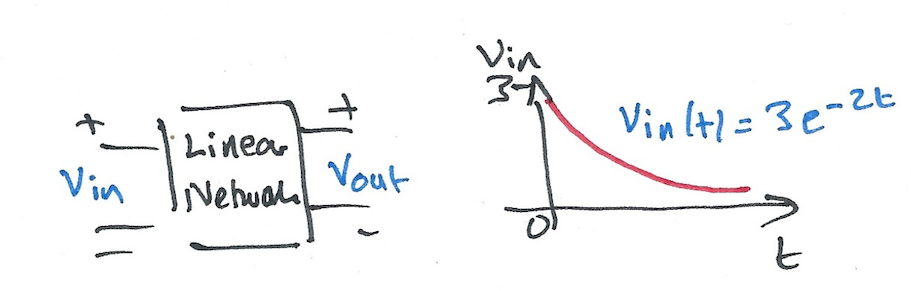

Worked solution: [ft3_ex3.pdf](https://cpjobling.github.io/eg-247-textbook/fourier_transform/solutions/ft3-ex3.pdf)

syms t w
H = 10/(j*w + 4)

Vin = fourier(3*exp(-2*t)*heaviside(t),t,w)

Vout=simplify(H*Vin)

vout = simplify(ifourier(Vout,w,t))

### Plot result

fplot(vout,[0,5])
title(['Solution to Example 3'])
ylabel('v_{out}(t) [V]')
xlabel('t [s]')
grid